clc; clearvars;

tempo_path = "C:\NERTO_drive\TEMPO_data";
tropomi_path = "C:\NERTO_drive\TROPOMI_data";
merged_path = "C:\NERTO_drive\merged_data_ams";

tempo_files = tempo_table(tempo_path);
tropomi_files = tropomi_table(tropomi_path);
merged_files = merged_table(merged_path);

## Plot tempo, tropomi, and merged data

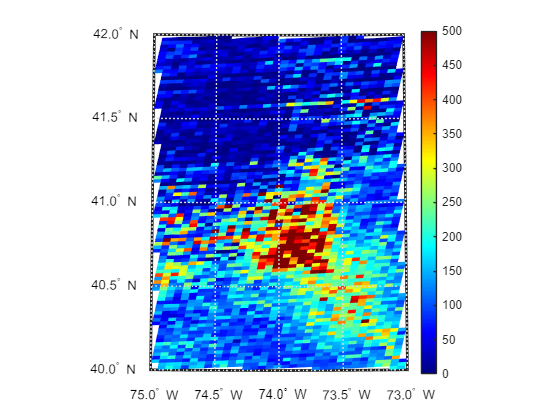

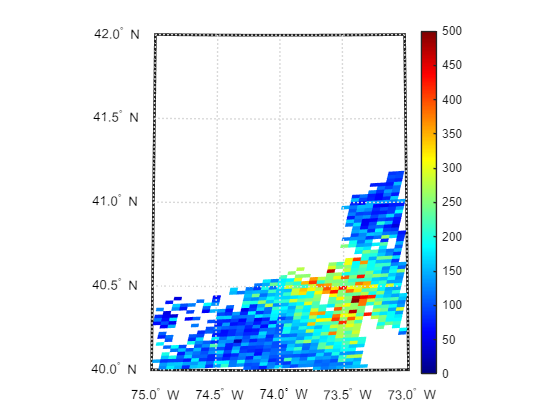

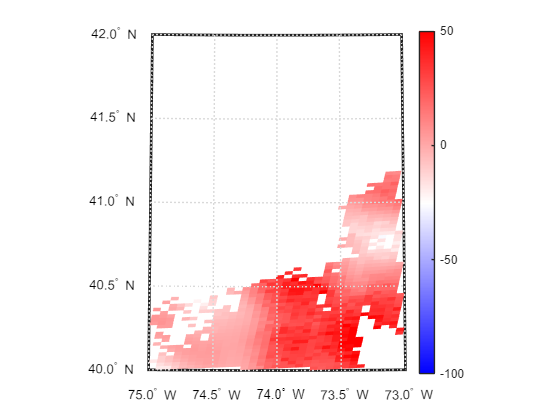

run_day = datetime("2024-01-03", "InputFormat", "uuuu-MM-dd"); run_day.TimeZone = 'UTC';
lat_bounds = [40 42];
lon_bounds = [-75 -73];


US_states = readgeotable('cb_2023_us_state_500k.shp');
lw = 1.5;
% font_size = 30;
% resolution = 300;
USA = load("./misc/USA.mat");
USA = USA.USA;

merged_files_day = merged_files(merged_files.Date>=run_day & merged_files.Date<run_day+days(1),:);
tempo_files_day = tempo_files(tempo_files.Date>=run_day & tempo_files.Date<run_day+days(1),:);
tropomi_files_day = tropomi_files(tropomi_files.Date>=run_day & tropomi_files.Date<run_day+days(1),:);

all_scans = intersect(unique(tempo_files_day.Scan), unique(merged_files_day.Scan));

mode = "single_scan";
scan_to_plot = all_scans(4);

color_lim_mode = "auto";
color_lim_no2 =  [0 500];
color_lim_diff = [-100 50];

if mode == "single_scan"
    scans_to_plot = scan_to_plot;
elseif mode == "full_day"
    scans_to_plot = all_scans;
end

figure;
t_tempo = tiledlayout(1,length(scans_to_plot));

figure;
t_merged = tiledlayout(1,length(scans_to_plot));

figure;
t_diff = tiledlayout(1,length(scans_to_plot));

for i = 1:length(scans_to_plot)
    scan_to_plot = scans_to_plot(i);

    [tempo_lat,tempo_lon,tempo_no2] = concate_tempo_scan(tempo_files_day,scan_to_plot);
    tempo_no2 = tempo_no2 .* 10^6 ./ conversion_factor('trop-tempo');

    nexttile(t_tempo,i);
    usamap(lat_bounds, lon_bounds);
    hold on;
    surfm(tempo_lat,tempo_lon,tempo_no2);
    % geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
    hold off;
    if i == length(scans_to_plot)
        colorbar;
    end
    ax = gca;
    ax.CLim = color_lim_no2;
    colormap(gca,'jet');


    merged_file = merged_files_day(merged_files_day.Scan == scan_to_plot,:);
    merged_lat = ncread(merged_file.Filename, "/geolocation/latitude");
    merged_lon = ncread(merged_file.Filename, "/geolocation/longitude");
    merged_no2 = ncread(merged_file.Filename, "/product/vertical_column_troposphere") .* 10^6;

    nexttile(t_merged,i);
    usamap(lat_bounds, lon_bounds);
    hold on;
    surfm(merged_lat,merged_lon,merged_no2);
    % geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
    hold off;
    if i == length(scans_to_plot)
        colorbar;
    end
    ax = gca;
    ax.CLim = color_lim_no2;
    colormap(gca,'jet');

    no2_diff = merged_no2 - tempo_no2;

    nexttile(t_diff,i);
    usamap(lat_bounds, lon_bounds);
    hold on;
    surfm(merged_lat,merged_lon,no2_diff);
    % geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
    hold off;
    if i == length(scans_to_plot)
    cb = colorbar;
    end
    ax = gca;
    ax.CLim = color_lim_diff;
    colormap(gca,USA);
end

## Time Average

start_day = datetime("2024-07-01", "InputFormat", "uuuu-MM-dd"); start_day.TimeZone = 'UTC';
end_day =   datetime("2024-07-01", "InputFormat", "uuuu-MM-dd"); end_day.TimeZone = 'UTC';

tempo_files_avg = tempo_files(tempo_files.Date>=start_day & tempo_files.Date<end_day+days(1),:);
tropomi_files_avg = tropomi_files(tropomi_files.Date>=start_day & tropomi_files.Date<end_day+days(1),:);
merged_files_avg = merged_files(merged_files.Date>=start_day & merged_files.Date<end_day+days(1),:);


process_avg = true;
if process_avg == true
    [lat_grid, lon_grid, tempo_no2_avg, tempo_no2_u_avg] = plot_results_avg(tempo_files_avg.Filename, './validation/average_data/test.mat', 'tempo', true);
    [~, ~, tropomi_no2_avg, tropomi_no2_u_avg] = plot_results_avg(tropomi_files_avg.Filename, './validation/average_data/test.mat', 'tropomi', true);
    [~, ~, merged_no2_avg, merged_no2_u_avg] = plot_results_avg(merged_files_avg.Filename, './validation/average_data/test.mat', 'merged', true);
end

Calculating averages



figure;
usamap(lat_bounds,lon_bounds)
surfm(lat_grid, lon_grid, tempo_no2_avg)
colormap('jet');
colorbar;
title('TEMPO')

figure;
usamap(lat_bounds,lon_bounds)
surfm(lat_grid, lon_grid, tropomi_no2_avg)
colormap('jet');
colorbar;
title('TROPOMI')

figure;
usamap(lat_bounds,lon_bounds)
surfm(lat_grid, lon_grid, merged_no2_avg)
colormap('jet');
colorbar;
title('MERGED')

function [full_lat, full_lon, full_no2] = concate_tempo_scan(tempo_files, scan)
    tempo_dim = [2048, 1400];
    tempo_files = tempo_files(tempo_files.Scan==scan,:);
    tempo_files = sortrows(tempo_files, "Granule", "ascend");

    full_lat = NaN(tempo_dim);
    full_lon = NaN(tempo_dim);
    full_no2 = NaN(tempo_dim);

    for i = 1:height(tempo_files)
        ncid = netcdf.open(tempo_files.Filename(i), 'NOWRITE');x
        product_id = netcdf.inqNcid(ncid, 'product');
        geolocation_id = netcdf.inqNcid(ncid, 'geolocation');

        step_varid = netcdf.inqVarID(ncid, 'mirror_step');
        lat_varid = netcdf.inqVarID(geolocation_id, 'latitude');
        lon_varid = netcdf.inqVarID(geolocation_id, 'longitude');
        no2_varid = netcdf.inqVarID(product_id, 'vertical_column_troposphere');
        
        % Read the variables
        mirror_step = netcdf.getVar(ncid, step_varid);
        temp_lat = netcdf.getVar(geolocation_id, lat_varid);
        temp_lon = netcdf.getVar(geolocation_id, lon_varid);
        temp_no2 = netcdf.getVar(product_id, no2_varid);

        % Close the NetCDF file
        netcdf.close(ncid);

        full_lat(:,mirror_step+1) = temp_lat;
        full_lon(:,mirror_step+1) = temp_lon;
        full_no2(:,mirror_step+1) = temp_no2;
    end
end